# **This scripting feature is like the jupyter**

% Decompaction and backstripping of a single well
function [tectonic_subsidence, age, base_depth_of_bottom_layer] = Decompaction(well_path, well, figure_path, data_path)

% parameter explanation:
%   well_path: path to well data
%   well: well name
%   figure_path: path to saving figure
%   data_path: path to saving computed data

%% --- Caveats and prerequisites ---
%   1. erosion should be recovered, otherwise the decompacted total subsidence is not correct.
%   2. use true vertical depth （TVD） instead of measured depth when doing stratigraphic correlation in Petrel

%% --- Define physical constants ---
water_density = 1000; % water density in kg/^3. 
mantle_density = 3300; % mantle density in kg/m^3
compaction_constant_unit = "km";
age_sequence = "normal";

%% --- Read well data from text file ---
fileID = fopen(well_path);
% File columns: well_name division top_depth bottom_depth top_age bottom_age density
% compaction_constant surface_porosity basin_setting lithology
well_info = textscan(fileID,'%s %s %f %f %f %f %f %f %f %f %s');

% Extract columns
z_top = well_info{3}; % top depth of each layer (m)
z_base = well_info{4}; % bottom depth of each layer (m)
agetop = well_info{5}; % age of formation top
agebase = well_info{6}; % age of formation base
sed_density = well_info{7}; % density of sediments of each unit
compaction_const = well_info{8}; % compaction constant
surface_porosity = well_info{9}; % surface porosity of each unit
basin_setting = well_info{10}; % basin_setting: continental or oceanic

%% --- Optionally reverse layer order ---
if age_sequence == "normal"
    z_top = flip(z_top);
    z_base = flip(z_base);
    agetop = flip(agetop);
    agebase = flip(agebase);
    sed_density = flip(sed_density);
    compaction_const = flip(compaction_const);
    surface_porosity = flip(surface_porosity);
    basin_setting = flip(basin_setting);
end

%% --- Unit conversion ---
% compaction_constant_unit == "km"
if compaction_constant_unit == "km"
    z_top = z_top ./ 1000;
    z_base = z_base ./ 1000;
end


# **Processing the data (Build well strata thickness matrix)**

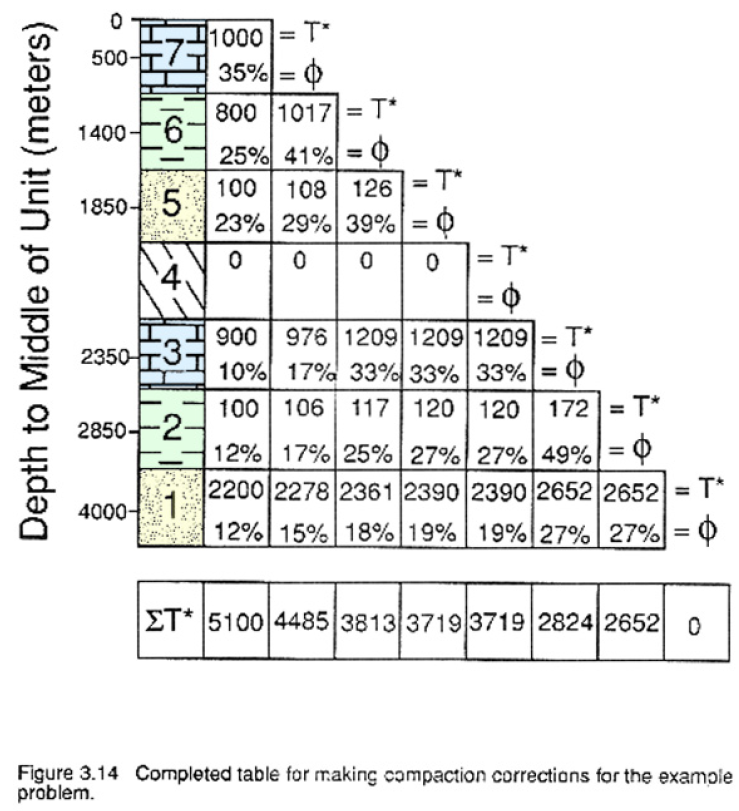

Reference: Angevine et al., 1990, p30.

% Avoid division by zero by replacing 0 with a small value
number_of_unit = size(compaction_const, 1); 
for i=1:number_of_unit 
    if compaction_const(i)==0
        compaction_const(i)=0.0001;
    end
end

% unit_top_matrix holds the depth to the top of each unit at each time;
% unit_base_matrix holds the depth to the base of each unit at each time;
% (unit_base_matrix - unit_top_matrix) holds the thickness of the each
% unit at each time.

for i = 1:number_of_unit
    for j = i:-1:1 % for top layer. We move the top layer of target layers to the surface
        if j == i
            unit_top_matrix(j,i) = 0;
        else % for other layers below top layer
            unit_top_matrix(j,i) = unit_base_matrix(j+1,i); 
        end
        % layer_thickness = z_base(j) - z_top(j)
        % base_depth = layer_thickness + top_depth
        unit_base_matrix(j,i) = z_base(j) - z_top(j) + unit_top_matrix(j,i);
    end
end

# **Decompact to obtain total subsidence at each stage**

% solve equation 8.23 or equation [A56.7] in Allen and Allen, 2013
% Decompaction by solving the equation numerically

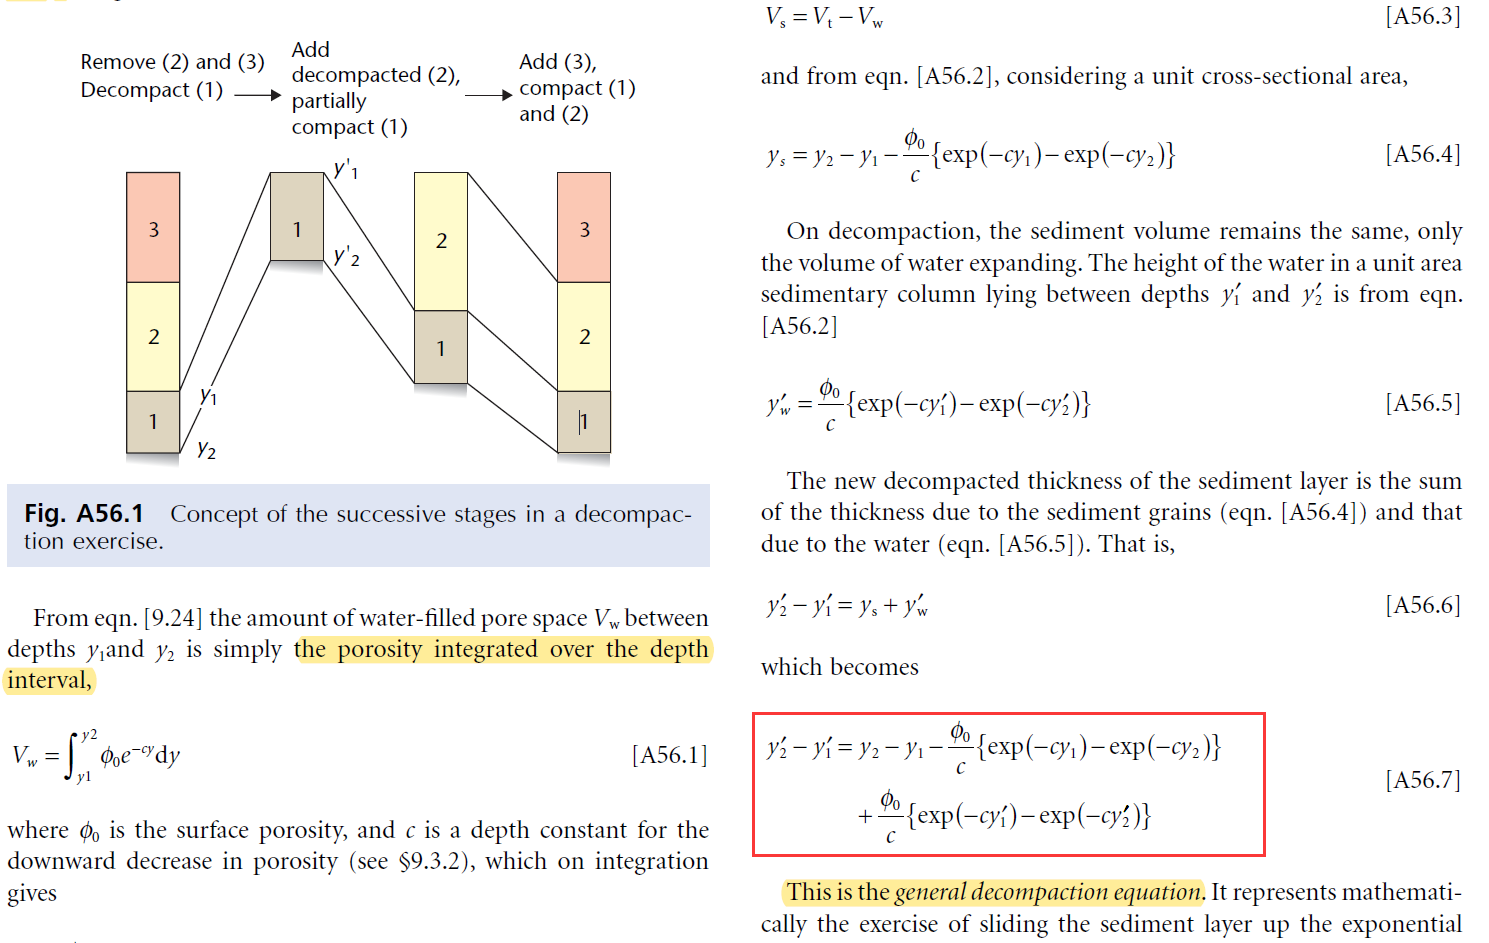

for i = 1:number_of_unit
    for j = i:-1:1
        if j == i
            unit_top_matrix(j,i) = 0;
        else
            % renew the unit_top_matrix
            unit_top_matrix(j,i) = unit_base_matrix(j+1,i);
        end
        options=optimset('display','off');
        % 'fzero' solves the roots of function near specified value x0. fzero
        % This function is used to solve the equation 8.23 in Allen and Allen
        % The algorithm of fzero is easy to understand. Use "help fzero" for
        % details. 
        % Function below will find the roots that make allque=0
        % near the initial value of unti_base_matrix(j,i).
        
        yy = fzero('allequ',unit_base_matrix(j,i),options,unit_top_matrix(j,i),z_base(j),z_top(j),surface_porosity(j),compaction_const(j));
        unit_base_matrix(j,i) = yy;
    end
end

% The unit_top_matrix, unit_base_matrix is not intuitive, so I transform them to more intuituve ones.
% 'decompacted_unit_top_thickness_transformed' and 'decompacted_unit_base_thickness_transformed' hold the depth to the top and base of each unit at each time
% step in a more intuitive way. 'decompacted_layer_thickness' holds the thickness of each unit at each time step 

decompacted_unit_top_thickness_transformed = zeros(number_of_unit, number_of_unit);
decompacted_unit_base_thickness_transformed = zeros(number_of_unit, number_of_unit);
for i = 1: number_of_unit
    n = number_of_unit;
    for j = 1:number_of_unit
        decompacted_unit_top_thickness_transformed(i,j) = unit_top_matrix(n-i+1,n-j+1);
        decompacted_unit_base_thickness_transformed(i,j) = unit_base_matrix(n-i+1,n-j+1);
    end
end
decompacted_layer_thickness = decompacted_unit_base_thickness_transformed- decompacted_unit_top_thickness_transformed;

% write the decompaction matrix to text file. 
% decompacted_layer_thickness stores the thickness of each layer after decompaction
decompacted_layer_thickness_path = data_path + well + '_thickness_of_each_unit_after_decompaction.xls';
writematrix(decompacted_layer_thickness, decompacted_layer_thickness_path);
layer_base_depth_path = data_path + well + '_base_depth_of_each_unit_after_decompaction.xls';
writematrix(unit_base_matrix,layer_base_depth_path);

# **Plot TOTAL subsidence of each well**

% depth_of_bottom_layer refers to the depth of bottom layer at each time or in ther words, the thickness of whole
% stratigraphic column at each stage. Simplely put, we are tracking how the bottom layer subsided over time.

base_depth_of_bottom_layer = [0, unit_base_matrix(1,:)];
% plot cumulative subsidence curve of each well
figure(1)
age = [agebase' agetop(size(agetop,1))];
plot(-age, base_depth_of_bottom_layer,'-o')
axis ij % reverse the label of x axis
set(gca, 'XAxisLocation', 'top')
xlabel('Age (Ma)')
ylabel('Total subsidence')
well_title = 'Cumulative subsidence curve of well ' + well;
title(well_title) % plot figure title

% save the figure
figure_exported_path = figure_path + "/decompaction/total subsidence of " + well;
img = gcf;
print(img, '-dpng', '-r500', figure_exported_path) % save figure into local disk

# Calculate TECTONIC subsidence based on Airy (local) isostasy. 

# This is optional since you will extract residual subsidence using flexural modeling

%=====================================================================
% sediment load correction, namely, the isostatic backstripping process.
% Note that the backstripping here is based on local isostasy/Airy
% isostasy. For Airy backstripping, it can be easily done employing an
% equation. But for foreland basin, we need to do flexural backstripping instead.
%=====================================================================

% ++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% calculate average density of entire stratigraphic column at each time

% thickness represents the thickness of each layer at each time
unit_thickness_matrix = unit_base_matrix - unit_top_matrix;
% stratigraphic_column_thickness represents the thickness of the entire sedimentary column at a given time
%   stratigraphic_column_thickness
stratigraphic_column_thickness = unit_base_matrix(1,:);
rhos = zeros(number_of_unit,1); % preallocate
tectonic_subsidence = zeros(number_of_unit, 1); % preallocate
for i = 1:number_of_unit
    for j = i:-1:1
        % call porosity function to calculate the average porosity of a
        % layer between depths y1 and y2. This function returns the average
        % porosity. Note the porosity versus depth is not linear but
        % exponential. Therefore, the average porosity is computed using
        % integration.
       	phi = porosity(unit_base_matrix(j,i),unit_top_matrix(j,i),surface_porosity(j),compaction_const(j));
        % pb represents the average density of a unit. Note that sediment
        % density used here is dry density of sediments 
       	pb = phi * water_density + (1-phi) * sed_density(j);
        
        % rhos represents the average density of the whole stratigraphic column at each time
        % rhos = effective density of the entire sedimentary column at a given time
        % refer to the Allen & Allen,2012, chapater 9 for detail. 
        if stratigraphic_column_thickness(i) == 0
            rhos(i) = rhos(i) + 0;
        else
            rhos(i) = rhos(i) + pb * unit_thickness_matrix(j,i) / stratigraphic_column_thickness(i);
        end
    end
    
    % ++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
    % calculate water loaded tectonic subsidence without paleowater
    % correction and sea level change correction at each time step, which
    % means those are not final values. This is possible because the
    % equation is in such a way that the water depth and sea level change
    % are items that are only added at the end of the equation. This means
    % that not including those two factors in the equation won't influence
    % the results of the Airy backstripping. Initial water depth would
    % influence the result of bastripping significantly if it is deep
    % enough (see figure below for explanation). However, for intracontinental basin with several meters of
    % water depth, it is negligible.   

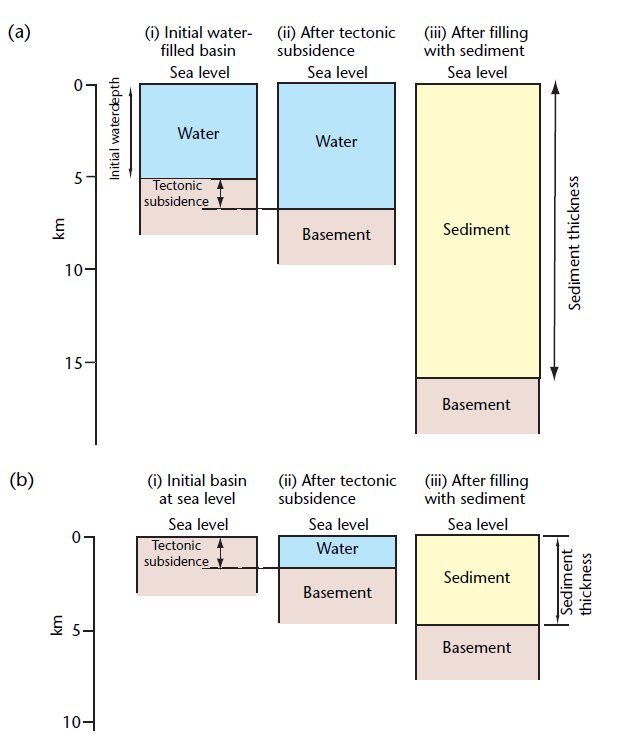  

    % tectonic subsidence here represents tectonic subsidence component without water correction and sea
    % level correction
    
    % Note that the author divides them into two categories, the
    % continental setting and the oceanic setting.
    % 2 for continent setting while 1 for oceanic setting. It seems that
    % basin setting 2 is for backstripping without water load.
    
    % You should understand the concept of isostasy in depth. As you can see, the tectonic subsidence
    % without water depth correction and sea level correction could be
    % expressed by a very neat equation, which is totally dependent on
    % the ratio between density difference of mantle-sediment and
    % density difference of mantle-water or mantle-air. This means you can 
    % have a sense of the magntitude of tectonic subsidence and magntitude
    % of subsidence contributed by sediment loads.
    if basin_setting(i)==1
        % for oceanic setting, the density difference is the difference
        % between mantle and water. 
        tectonic_subsidence(i) = stratigraphic_column_thickness(i) * (mantle_density - rhos(i)) / (mantle_density - water_density); 
    elseif basin_setting(i)==2
        % for continental setting, the density difference is the difference
        % between mantle and air, which means tectonic subsidence here is
        % air-loaded tectonic subsidence instead of water-loaded tectonic subsidence.
        tectonic_subsidence(i) = stratigraphic_column_thickness(i) * (mantle_density - rhos(i)) / (mantle_density);
    end
end

tectonic_subsidence = [0, tectonic_subsidence'];

# Plot TECTONIC subsidence calculated based on Airy isostasy

% plot(-age, Compacted_thickness, 'kx-', -age, Total_decompacted_thickness, 'r+-', -age, Ym, 'b.-')
plot(-age, base_depth_of_bottom_layer, 'r.-', -age, tectonic_subsidence, 'b.-')
% specify the location of axis
set(gca, 'XAxisLocation', 'top', 'YAxisLocation', 'left')
legend('Decompacted total subsidence','Backstripped Tectonic subsidence');
% axis([-agebase(1) -agetop(numer_of_unit) Total_decompacted_thickness(1) Total_decompacted_thickness(numer_of_unit+1)]);

axis ij;
xlabel('Age (Ma)');
ylabel('Decompacted depth (km)');
figure_title = 'Total subsidence and tectonic subsidence of well ' + string(well);
title(figure_title)

figure_exported_path = figure_path + "/decompaction/Decompacted subsidence curve of well " + string(well);
img = gcf;
print(img, '-dpng', '-r300', figure_exported_path) % save figure into local disk